# **Laboratorio 1: Problemas de contorno unidimensionales, métodos de disparo**

**Métodos Numéricos Aplicados 2**

**Máster en Ingeniería Matemática y Computación**

*Javier Blanco Álvarez*

Cuatrimestre II

## **Descripción**

Con la presente práctica aplicaremos el método del disparo con Secante y Newton para resolver problemas de contorno (PC) de segundo orden no lineales y con condiciones No Dirichlet. 

Consideremos el siguiente problema de contorno 


$${y^{\prime } }^{\prime } +y^{\prime } y-2=2\mathrm{xy},\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\in \left\lbrack 1,2\right\rbrack$$



$$\begin{array}{l}
y^{\prime } \left(1\right)-y\left(1\right)=\frac{1}{2}\\
y^{\prime } \left(2\right)+y\left(2\right)=\frac{17}{2}
\end{array}$$


Describiremos la solución para este PC considerando el esquema de la secante y de Newton, ambos con un $t_0 =0$, una tolerancia de $1\;\ldotp {10}^{-8}$ y 10 subintervalos. Ambos esquemas serán implemenados en Matlab version 2021b. 

## Planteamiento Secante. 

El PC considerado también podemos expresarlo de ls siguiente forma:


$${y^{\prime } }^{\prime } =2\mathrm{xy}-y^{\prime } y+2$$


tratándose de un problema no lineal y con condiciones no Dirichlet, hemos de transformar nuestro problema a uno de valor inicial, además añadiremos la aproximación de un parámetro $t$. Por consiguiente, el PC como PVI queda expresado:


$$\begin{array}{l}
y\left(1\right)=t,\\
y^{\prime } \left(1\right)=\frac{1}{2}+t
\end{array}$$


Transformamos nuestro PVI de segundo orden a un sistema de ecuaciones diferenciales de primero orden mediante cambio de variable, quedando expresado de la siguiente forma:


$$\begin{array}{l}
y_1 =y;y_2 =y^{\prime } ;y_3 ={y^{\prime } }^{\prime } \\
{y^{\prime } }_1 =y_2 ;{y^{\prime } }_2 ={y^{\prime } }^{\prime } 
\end{array}$$


El sistema de ecuaciones sería el siguiente:

$\left[\matrix{ y'_{1} =y_{2} \cr y'_{2} = 2xy_{1} - y_{2}y_{1} + 2} \right]$;$\left[\matrix{ y_{1}\cr y_{2}} \right]$= $\left[\matrix{ t \cr \frac{1}{2} + t} \right]$

Con el sistema de ecuaciones diferenciales de primer orden ya establecido hemos de determinar nuestro valor de t, el cual se ha de aproximar al valor de $\beta$, que en este caso es 17/2. Para ello, planteamos el siguiente criterio de parada:


$$\left|y^{\prime } \left(2\right)+y\left(2\right)-\frac{17}{2}\right|\le {1\ldotp 10}^{-8}$$


Así, el método de la secante vendrá expresado de la siguiente forma:


$$t_k =t_{k-1} -\left\lbrack \frac{\left(t_{k-1} -t_{k-2} \right)\left(y^{\prime } \left(b,t_{k-1} \right)+y\left(b,t_{k-1} \right)-\frac{17}{2}\right)}{\left(y^{\prime } \left(b,t_{k-1} \right)+y\left(b,t_{k-1} \right)-\frac{17}{2}\right)-\left(y^{\prime } \left(b,t_{k-2} \right)+y\left(b,t_{k-2} \right)-\frac{17}{2}\right)}\right\rbrack$$


Donde:


$$\begin{array}{l}
t_{k-2} =t_0 =0\\
t_{k-1} =t_1 =\left(\frac{\beta -\alpha }{b-a}\right)
\end{array}$$


## Implementación Secante

El PVI ha sido definida en la función '*actividad1_s.m*'.

El método del disparo con Secante se ha definido en la función '*DisparoSecanteAct1.m*'

procedemos a ejecutar la solución en el siguiente script:

clear, clc
digits(300)
format shortG

%PARAMETERS
a = 1;
b = 2;
alfa = 1/2;
beta = 17/2;
n = 10;
tol = 1e-8;
maxiter = 100;
I = 0:1:n;

%METHODS

[xs,ys,ts,iter_s]=DisparoSecanteAct1('actividad1_s',a,b,alfa,beta,n,tol,maxiter);

t = table(I', xs,vpa(ys(:,1),15),vpa(ys(:,2),15), ...
    'VariableNames',{'I','x','Y Secante', ...
    'dY Secante'});
disp(t)

    I      x        Y Secante           dY Secante   
    __    ___    ________________    ________________

     0      1    1.5000000015882     2.0000000015882 
     1    1.1    1.71000000173511    2.20000000135434
     2    1.2    1.94000000185896    2.4000000011302 
     3    1.3    2.19000000196102    2.60000000092128
     4    1.4    2.46000000204306    2.80000000073225
     5    1.5    2.75000000210728    3.00000000056655
     6    1.6    3.06000000215614    3.20000000042601
     7    1.7    3.39000000219223    3.40000000031086
     8    1.8    3.74000000221804    3.60000000021985
     9    1.9    4.11000000223592    3.80000000015052
    10      2    4.50000000224788    4.00000000009969



El Resultado Gráfico:

hold on
plot(xs, ys(:,1),'*b')
plot(xs, ys(:,2),'-r')
grid on
legend('Y Secante', 'dY Secante')
hold off

Comprobamos que la solución obtenida sea correcta si evaluamos los resultados de y e y' con las condiciones de contorno, así:

ys(1,2) - ys(1,1)

ans =           0.5


ys(end,2) + ys(end,1)

ans =           8.5


## Planteamiento Newton

`por hacer`

## Implementación Newton

El PVI ha sido definida en la función '*actividad1_n.m*'.

El método del disparo con Secante se ha definido en la función '*DisparoNewtonAct1.m*'

procedemos a ejecutar la solución en el siguiente script:

clear, clc
digits(300)
format shortG

%PARAMETERS
a = 1;
b = 2;
alfa = 1/2;
beta = 17/2;
n = 10;
tol = 1e-8;
maxiter = 100;
I = 0:1:n;

%METHODS

[xn,yn,tn,iter_n]=DisparoNewtonAct1('actividad1_n',a,b,alfa,beta,n,tol,maxiter);

t = table(I', xn,vpa(yn(:,1),15),vpa(yn(:,2),15), ...
    'VariableNames',{'I','x','Y Newton', ...
    'dY Newton'});
disp(t)

    I      x         Y Newton           dY Newton    
    __    ___    ________________    ________________

     0      1    1.5000000024864     2.0000000024864 
     1    1.1    1.71000000271639    2.20000000212027
     2    1.2    1.94000000291029    2.40000000176937
     3    1.3    2.19000000307006    2.6000000014423 
     4    1.4    2.4600000031985     2.80000000114638
     5    1.5    2.75000000329904    3.00000000088695
     6    1.6    3.06000000337554    3.20000000066693
     7    1.7    3.39000000343202    3.40000000048667
     8    1.8    3.74000000347244    3.60000000034419
     9    1.9    4.11000000350042    3.80000000023565
    10      2    4.50000000351915    4.00000000015607



Graficamos la solución:

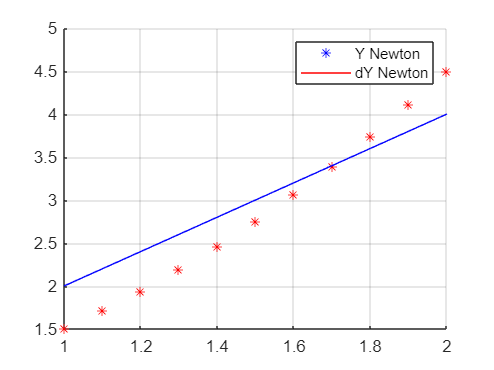

hold on
plot(xn, yn(:,1),'*r')
plot(xn, yn(:,2),'-b')
grid on
legend('Y Newton', 'dY Newton')
hold off

## Comparación de resultados

## Conclusiones

## Bibliografía

## **Funciones**

function dy = actividad1_s(x,y)
dy = [y(2);2.*x.*y(1)-y(2).*y(1)+2];
end
function dy = actividad1_n(x,y)
dy = [y(2);2.*x.*y(1)-y(2).*y(1)+2;y(4);-y(1).*y(4) + 2.*x.*y(3) - y(3).*y(2)];
end
function [t, Y] = Heun_Systems(f,a,b,N,Ya)
h = (b - a) / N;
t = a:h:b;
t = t(:);
Y = zeros(N+1, length(Ya));
Y(1,:) = Ya;
for k=1:N
    k1 = h*feval(f,t(k), Y(k,:))';
    k2 = h*feval(f, t(k+1), Y(k,:) + k1)';
    Y(k+1,:) = Y(k,:) + (k1 + k2) / 2;
end
end
function [nodos,solaprox,t,iter] = DisparoSecanteAct1(funcion,a,b,alfa,beta,n,tol,maxiter)
h=(b-a)/(n+1);  
x=a:h:b;  
x=x(:);

t0=0;
% [x,Y]= ode45(funcion,x,[alfa,t0]');
[x,Y]= Heun_Systems(funcion,a,b,n, [t0,((1/2)+t0)]);
% [x,Y]= AdamsBashforth4Systems(funcion,a,b,n,[t0,((1/2)+t0)]);
% [x,Y]= ABM2Systems(funcion,a,b,n,[alfa,t0]);
yb0=Y(end,1);
yb0prima = Y(end,2);

t1=(beta - alfa)/(b-a);
% [x,Y]= ode45(funcion,x,[alfa ,t1]');
[x,Y]= Heun_Systems(funcion,a,b,n, [t1,((1/2)+t1)]);
% [x,Y]= AdamsBashforth4Systems(funcion,a,b,n,[t1,((1/2)+t1)]);
% [x,Y]= ABM2Systems(funcion,a,b,n,[alfa,t1]);
yb1=Y(end,1);
yb1prima = Y(end,2);
iter=1; 
% incre=abs(yb1-beta);
incre = abs(yb1prima + yb1 - beta);


while incre > tol && iter < maxiter
%     t=t1 -(t1 -t0)*(yb1 -beta )/(yb1 -yb0);
    t = t1 - (t1-t0)*(yb1prima + yb1 - beta)/((yb1prima + yb1 - beta) - (yb0prima + yb0 - beta));
    [x,Y]= Heun_Systems(funcion,a,b,n,[t,((1/2)+t)]);
%     [x,Y]= AdamsBashforth4Systems(funcion,a,b,n,[t,((1/2)+t)]);
%     [x,Y]= ABM2Systems(funcion,a,b,n,[alfa,t]);
%     [x,Y]= ode45(funcion ,x ,[alfa ,0, t]');
    incre =abs(Y(end,2) + Y(end,1) - beta); 
    iter= iter+1;
    t0=t1; 
    yb0=yb1;
    yb0prima = yb1prima;
    t1=t; 
    yb1=Y(end,1);
    yb1prima=Y(end,2);
end

if incre <= tol
nodos =x;
solaprox =Y;
else
disp('se necesitan mas iteraciones ')
end
end

function [nodos,solaprox,t,iter] = DisparoNewtonAct1(funcion,a,b,alfa,beta,n,tol,maxiter)

h=(b-a)/(n+1); 
x=a:h:b; 
% t0 =(alfa-beta)/(b-a);
t0=0;

% [x,Y]= ode45(funcion,x,[alfa,t0,0,1]');
[x,Y]= Heun_Systems(funcion,a,b,n, [t0,((1/2) + t0),1,1/2]);
% [x,Y]= AdamsBashforth4Systems(funcion,a,b,n, [t0,((1/2) + t0),1,1/2]);
% [x,Y]= ABM2Systems(funcion,a,b,n, [alfa,t0,0,1]);
yb1=Y(end,1); 
zb1=Y(end,3);
dy1 = Y(end,2);
iter=1; 
% incre=abs(Y(end,1)-beta);
incre = abs(dy1 + yb1 - beta);

while incre >tol && iter < maxiter
    t=t0-(dy1 +yb1-beta)/(zb1); %Metodo de Newton
    [x,Y]= Heun_Systems(funcion,a,b,n,[t,((1/2) + t),1,1/2]);
%     [x,Y]= AdamsBashforth4Systems(funcion,a,b,n, [t,((1/2) + t),1,1/2]);
%     [x,Y]= ode45(funcion,x,[alfa,t,0,1]');
%     [x,Y]= ABM2Systems(funcion,a,b,n, [alfa,t,0,1]);
%     incre=abs(Y(end,1)-beta);
    incre = abs(Y(end,2) + Y(end,1) - beta);
    iter= iter+1;
    t0=t; 
    yb1=Y(end,1); 
    zb1=Y(end,3);
    dy1 = Y(end,2);
end
if incre <= tol
nodos =x; 
solaprox=Y;
else
disp('se necesitan mas iteraciones ')
end
end
